# Simulating LIDAR Sensor Noise

Objective: This script will show you how to use *ExpectedMeasurementLIDAR* to predict the expected measurement of a LIDAR sensor given a map and how to simulate noisy sensor measurements for a stationary robot. 

Helper Functions used in this exercise:

- *plot_measurements* shows the simulated LIDAR measurements. On the left, plots the true expected LIDAR measurement of each LIDAR angle reading (without noise) overlayed on the Map. On the right, plots multiple measurements with noise. 

Execise:

After inspecting and understanding the *ExpectedMeasurementLIDAR* function, you will test the function to simulate and plot noisy measurements for a stationary robot. 

Complete the code below to:

- Initialize the robot and define sensor parameters

- Use *ExpectedMeasurementLIDAR* to estimate the expected measurement for each LIDAR reading. 

- Define the noise distribution that will be added to the expected measurement

**COMPLETE THE CODE BELOW**

% 1. Initialization 

%Initial robot position
robotXY = [1.25;1;0]; %Insert code here
map = load('MAP102M1.txt');%TO DO: NEED TO LOAD THIS MAP FROM RELATIVE PATH (AA doesn't know how to do this)
maxRange = 4; 

%Simplify the LIDAR sensor and assume assume that it takes only 4 range measurements that are 90 degrees apart. 
alpha = [pi, pi/2, 0, -pi/2]; %insert code here


We use *ExpectedMeasurementLidar* to estimate the expected measurements from each angle (in alpha) of the LIDAR range sensor. This function assumes the sensor has the pose $[0.13, 0, 0]$ in the reference frame of the robot.

%2. Estimate the expected measurement for the LIDAR
measurement = ExpectedMeasurementLidar(robotXY,alpha,map,maxRange);

%3. Define noise distribution

variance = [0.1 0.3 0.1, 0.3];
Q = diag(variance);

The built-in MATLAB function randn pulls random numbers from a normal distribution with mean zero and standard deviation 1, therefore we scale by the sqrt of the variances. Moving the slider above will plot the noisy measurements as connected dots, the mean of the noisy measurements as a dotted line, and the true expected measurement as a solid line. 

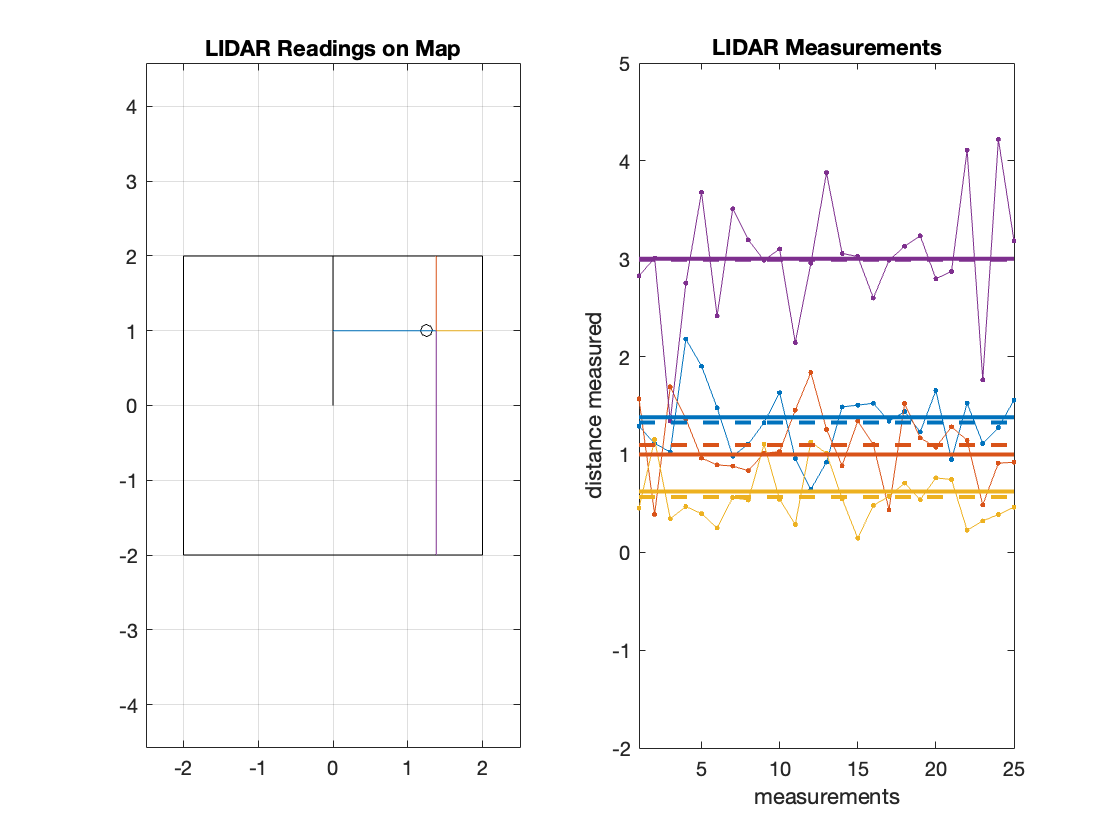

N = 25; % number of measurements
measurements = repmat(measurement',N,1) + randn(N,length(measurement))*sqrt(Q);
plot_measurements(N, measurements, alpha, measurement,robotXY, map);
set(gcf,'Visible','on'); 

Expected Results:  On the left, plots the true expected LIDAR measurement of each LIDAR angle reading (without noise) overlayed on the Map. On the right, plots multiple measurements with noise. 

Check your Comprehension: Do your results make sense? Compare the expected measurement with the noisy measurements and the mean. Why can you not rely on the noisy measurements? 

To better understand the results:

-  try changing the x-y position of the robot (robot), the noise added (variance), and the number of measurements taken (N).  Where does the linearity assumption in the measurement model break?

- Create a different model for the simplified LIDAR - try adding more range measurements at different angles. 